% Script to test a homing routine for steering servo motors

% Number of startup measurements to sample from the potentiometer to get
% the initial startup position
N = 50;
% Choose an arbitrary true startup position
x_true_pos = 6*pi/180;
% Simulate N measurements of the startup position with noise from the pot
x_meas_startup = x_true_pos + randn(N,1)*pi/180;
% Set the location of the true home and the true index pulses
x_true_home = -1.125*pi/180;
x_true_index = (-2.5*pi/180*10:2.5*pi/180:2.5*pi/180*10)';

% Calculate the best estimate of the startup position from the average pot
% reading
x_calc_startup = mean(x_meas_startup);
% Compute the measurement offset from the true position
x_calc_offset = x_calc_startup - x_true_pos;

% Simulate a slightly noisy acquisition of the encoder counts at the home
% position
x_meas_home = x_true_home + x_calc_offset + (1/10)*randn(1,1)*pi/180;
% Simulate a perfectly accurate acquisition of the encoder counts at a
% nearby index pulse
%idx = find(abs(x_true_index - x_meas_home) <= 1.25*pi/180,1,'first');
idx = randi(length(x_true_index));
x_meas_index = x_true_index(idx) + x_calc_offset;

% Compute the distance from the home switch to the index pulse captured
dist_index_home = x_meas_index - x_meas_home;

% If the index pulse is to the left of the home switch,
if dist_index_home > 0
    x_calc_offset = x_meas_index - 2.5*pi/180*floor(dist_index_home/(2.5*pi/180));
else
    x_calc_offset = x_meas_index + 2.5*pi/180*ceil(abs(dist_index_home)/(2.5*pi/180));
end
disp(x_calc_offset)

    0.0032




% Calculate the final offset
x_true_offset = x_meas_index - x_true_index(idx)

x_true_offset = 0.0032


% Calculate the initial position to check the recovery
x_calc_pos = x_calc_startup - x_calc_offset

x_calc_pos = 0.1047

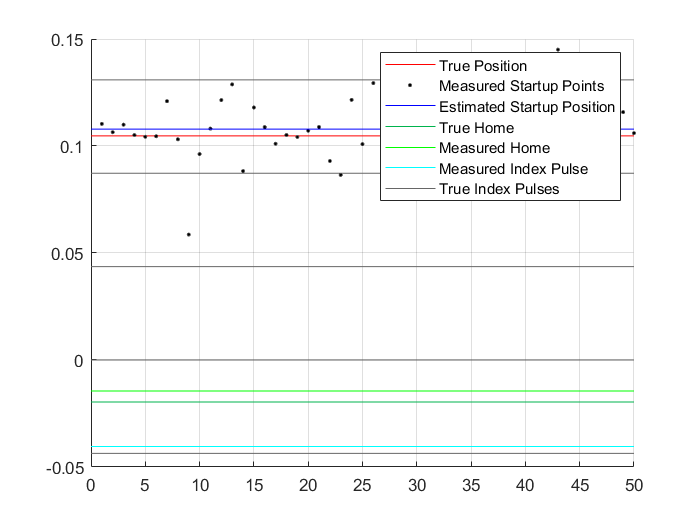


% Plot the results
figure(1)
clf
axis auto
hold on
grid on
plot([0 N],[1 1]*x_true_pos,'r-')
plot((1:N)',x_meas_startup,'k.');
plot([0 N],[1 1]*x_calc_startup,'b-')
plot([0 N],[1 1]*x_true_home,'-','color',[0 0.7 0.3])
plot([0 N],[1 1]*x_meas_home,'g-')
plot([0 N],[1 1]*x_meas_index,'c-');%,'linewidth',2)
axis manual
for i = 1:length(x_true_index)
    plot([0 N],[1 1]*x_true_index(i),'color',0.4*ones(1,3))
end
legend('True Position','Measured Startup Points','Estimated Startup Position','True Home','Measured Home','Measured Index Pulse','True Index Pulses')